clear; close; clc;

%flight condtion for cruise

% import salient characteristics of missile
load('CARTRIDGE_105_MILLIMETER_HERA_M927.mat')

d = CARTRIDGE_105_MILLIMETER_HERA_M927.Hydrolic_Diameter; % diameter (m)
l = CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length; % length (m)

d_noseTip = CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Tip_Diameter; % diamter of note tip (m)
l_N = CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Length; % nose length (m)

d_bt = CARTRIDGE_105_MILLIMETER_HERA_M927.Boattail_Diameter; % diameter of boattail (m)
A_E = CARTRIDGE_105_MILLIMETER_HERA_M927.Nozzle_Exit_Area; % area of the nozzle exit (m)

mass_wet = CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Mass; % wet mass of projectile (kg)
mass_propellant = CARTRIDGE_105_MILLIMETER_HERA_M927.Propellant_Mass; % mass of propellant (kg)

% compute relevant mass characteristics
g = 9.81 % acceleration due to gravity on earths surface (m/s^2)

g = 9.8100

mass_50 = mass_wet - (mass_propellant / 2); % mass at 50% fuel load (kg)
Weight_50 = mass_50 * g; % weight at 50% fuel load (N)

% compute geometric parameters
S_ref = pi*d/4; % refrence area from hydraulic diameter (m^2)

% dimentions that match fleeman graph
% for debugging
% S_ref = convlength(convlength(2,"ft","m"),"ft","m") % convert ft^2 to m^2
% d = 4 * S_ref / pi;
% d_noseTip = 0; % assumption
% d_bt = d; % assumption
% l = 10 * d;
% l_N = l * 3/10; % assumption
% A_E = 0; % assumption
% Weight_50 = convforce(2000,"lbf","N");

%height = 1000; % we will do this for various altitudes. not yet implemented
height = 0; % we will do this for various altitudes. not yet implemented



% initialize looop solution arrays
nPoints = 1000 % 1000 is a good number

nPoints = 1000


Lift = Weight_50; % lift for low angles of attack at 50% fuel load

%q_bars = logspace(2,4,nPoints) * 47.880259; % logspace in lb/ft^2 to Pa
q_bars = linspace(10^2,10^4,nPoints) * 47.880259; % linspace in lb/ft^2 to Pa

alpha_optimum = zeros(nPoints,0);
V_list = zeros(nPoints,0);


L_over_D_1g = zeros(nPoints,0);
L_over_D_1g_powered = zeros(nPoints,0);

syms alpha

for j = 1:nPoints
    q = q_bars(j);

    [~,a,~,rho] = atmosisa(height);
    V = sqrt(2*q/rho);
    V_list(j) = V;
    M = V/a;
    
    C_L = Lift/(S_ref*q);

    %VPA solve for alpha (produces same results as using Newton-Raphson)
    assume(alpha > 0);
    assumeAlso(alpha < deg2rad(15));

    % there are probably at least two possible alphas for all (but one) C_N
    %alpha_optimum(j) = double(vpasolve(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha) == C_L,alpha, .0001)); % this will gereate worse results
    alpha_optimum(j) = double(vpasolve(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha) == C_L,alpha, deg2rad(15)));

    L_over_D_1g(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), ...
        dragCoeff_zeroLift_body(M, q, l, l_N, d, d_noseTip, d_bt, A_E, true), ...
        alpha_optimum(j));

    % only impact of thrust is here (there seems to be no impact on L/D)
    L_over_D_1g_powered(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)), ...
        dragCoeff_zeroLift_body(M, q, l, l_N, d, d_noseTip, d_bt, A_E, true), ...
        alpha_optimum(j));
end

%cruise_results = {alpha_optimum, L_over_D_1g, L_over_D_1g_powered, q_bars} % as cell array
cruise_result.alpha_optimum = alpha_optimum;
cruise_result.alpha_optimum = q_bars;
cruise_result.L_over_D_1g = L_over_D_1g;
cruise_result.L_over_D_1g_powered = L_over_D_1g_powered;
cruise_result.alt = height;
%cruise_results = {cruise_result} % something like this to madd my results
%to the cell array

alpha_optimum

alpha_optimum =     0.1132    0.1049    0.0978    0.0917    0.0863    0.0815    0.0773    0.0735    0.0700    0.0669    0.0641    0.0615    0.0591    0.0569    0.0548    0.0529    0.0512    0.0495    0.0480    0.0465    0.0451    0.0439    0.0426    0.0415    0.0404    0.0394    0.0384    0.0375    0.0366    0.0357    0.0349    0.0342    0.0334    0.0327    0.0321    0.0314    0.0308    0.0302    0.0296    0.0291    0.0285    0.0280    0.0275    0.0270    0.0266    0.0261    0.0257    0.0253    0.0249    0.0245


L_over_D_1g

L_over_D_1g =     1.8913    1.7815    1.6794    1.5853    1.4987    1.4192    1.3463    1.2792    1.2175    1.1606    1.1081    1.0595    1.0144    0.9726    0.9336    0.8973    0.8633    0.8315    0.8017    0.7737    0.7474    0.7226    0.6991    0.6770    0.6560    0.6362    0.6174    0.5995    0.5824    0.5662    0.5508    0.5361    0.5220    0.5086    0.4957    0.4834    0.4716    0.4603    0.4494    0.4390    0.4290    0.4193    0.4100    0.4011    0.3925    0.3842    0.3762    0.3684    0.3610    0.3537


L_over_D_1g_powered

L_over_D_1g_powered =     1.8913    1.7815    1.6794    1.5853    1.4987    1.4192    1.3463    1.2792    1.2175    1.1606    1.1081    1.0595    1.0144    0.9726    0.9336    0.8973    0.8633    0.8315    0.8017    0.7737    0.7474    0.7226    0.6991    0.6770    0.6560    0.6362    0.6174    0.5995    0.5824    0.5662    0.5508    0.5361    0.5220    0.5086    0.4957    0.4834    0.4716    0.4603    0.4494    0.4390    0.4290    0.4193    0.4100    0.4011    0.3925    0.3842    0.3762    0.3684    0.3610    0.3537


q_bars

q_bars = 1.0e+05 *

    0.0479    0.0526    0.0574    0.0621    0.0669    0.0716    0.0763    0.0811    0.0858    0.0906    0.0953    0.1001    0.1048    0.1096    0.1143    0.1191    0.1238    0.1285    0.1333    0.1380    0.1428    0.1475    0.1523    0.1570    0.1618    0.1665    0.1712    0.1760    0.1807    0.1855    0.1902    0.1950    0.1997    0.2045    0.2092    0.2140    0.2187    0.2234    0.2282    0.2329    0.2377    0.2424    0.2472    0.2519    0.2567    0.2614    0.2661    0.2709    0.2756    0.2804


## plot the data

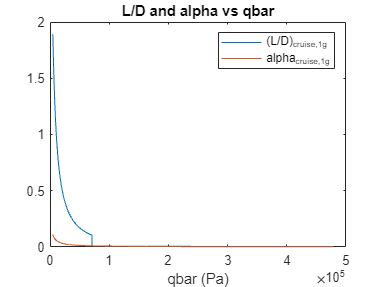

% plot trend of l/d and alpha
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D and alpha vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

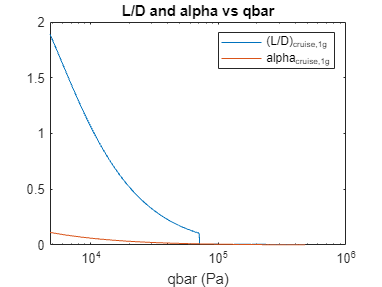

semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D and alpha vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

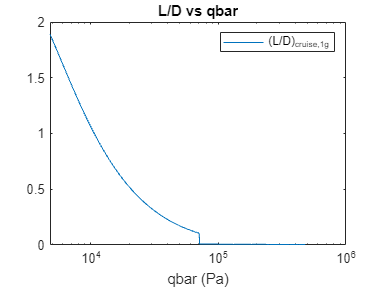


semilogx(q_bars,L_over_D_1g); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}"]);

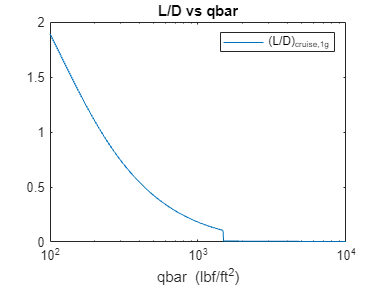

%to match fleeman
semilogx(q_bars/47.880259,L_over_D_1g); title("L/D vs qbar"); xlabel("qbar (lbf/ft^2)"); legend(["(L/D)_{cruise,1g}"]);

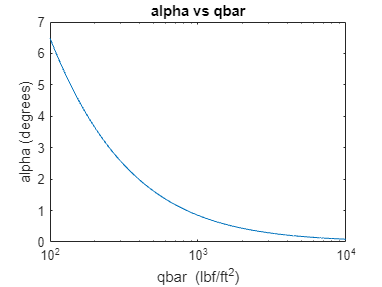


%alpha vs qbar
semilogx(q_bars/47.880259,rad2deg(alpha_optimum)); title("alpha vs qbar"); xlabel("qbar (lbf/ft^2)"); ylabel("alpha (degrees)");

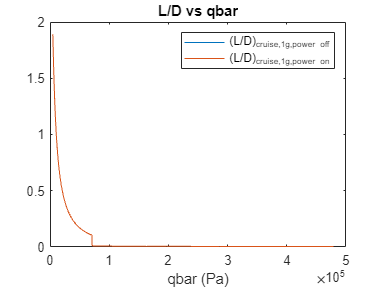


%compare powered and unpowerd
plot(q_bars,[L_over_D_1g; L_over_D_1g_powered]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g,power off}", "(L/D)_{cruise,1g,power on}"]); % this plot is unintresting as drag reduction is negligeable